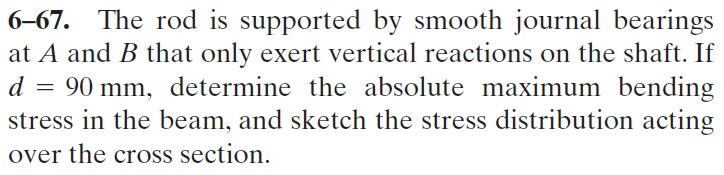

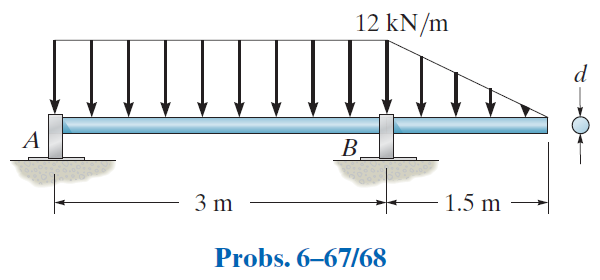

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-67P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-67P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
w1(x) = -12*u.kN/u.m;
w2 = findpoly(1, 'thru', [3*u.m -12*u.kN/u.m], 'thru', [4.5*u.m 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 3*u.m);
b = b.add('distributed', 'force', w1, [0 3]*u.m);
b = b.add('distributed', 'force', w2, [3 4.5]*u.m, [false true]);
b.L = 4.5*u.m;

# section properties

D = 90*u.mm;
b.I = rewrite(sympi*(D/2)^4/4, u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{1600000000\,x\,\left(x-3\,m\right)\,\left(-2\,x^{2}+5\,x\,m+15\,m^{2}\right)}{6561\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{5}} & \text{ if }x\leq 3\,m\\ \frac{320000000\,\left(x-3\,m\right)\,\left(4\,x^{4}-78\,x^{3}\,m+576\,x^{2}\,m^{2}-1917\,x\,m^{3}+2889\,m^{4}\right)}{19683\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{6}} & \text{ if }3\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{1600000000\,\left(8\,x^{3}-33\,x^{2}\,m+45\,m^{3}\right)}{6561\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{5}} & \text{ if }x\leq 3\,m\\ \frac{3200000000\,\left(2\,x^{4}-36\,x^{3}\,m+243\,x^{2}\,m^{2}-729\,x\,m^{3}+864\,m^{4}\right)}{19683\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{6}} & \text{ if }3\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{3\,x\,\left(4\,x-11\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ \frac{{\left(2\,x-9\,m\right)}^{3}}{6}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{3\,\left(8\,x-11\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ {\left(2\,x-9\,m\right)}^{2}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -12\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ 4\,\left(2\,x-9\,m\right)\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 16.5\,\mathrm{kN}\\ \mathrm{Rb} & 28.5\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

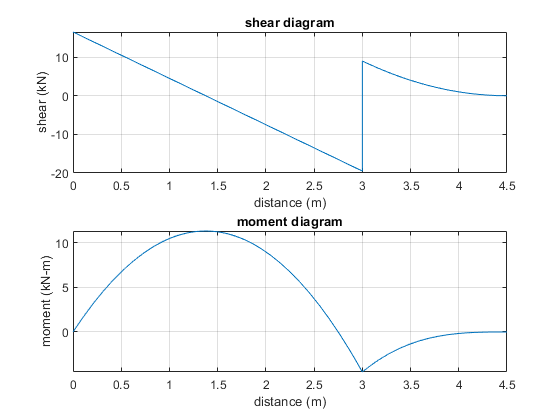

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# maximum bending moment

assume(0 < x & x < b.L);
xmax = solve(v == 0);
M_max = m(xmax);
M_max_vpa = vpa(M_max, 4) %#ok<NASGU> 

$$M\_max\_vpa = 11.34\,\mathrm{kN}\,m$$

# maximum bending stress

C = D/2;
b.I = rewrite(b.I, u.mm);
sigma_max = rewrite(M_max*C/b.I, u.MPa);
sigma_max_vpa = vpa(sigma_max, 5) %#ok<NASGU> 

$$sigma\_max\_vpa = 158.5\,\mathrm{MPa}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;
clear ra_vpa;
clear M_max_vpa;
clear sigma_max_vpa;